# **cuDSS plane-element solver comparison**

This notebook-style script compares the OpenSees CPU sparse solvers with the optional NVIDIA cuDSS backend. 

The model is a square plane-stress panel made from four-node quad elements. Its left edge is fixed and a uniformly distributed vertical load is applied to its right edge. The mesh is automatically selected to approach each requested number of active equations.

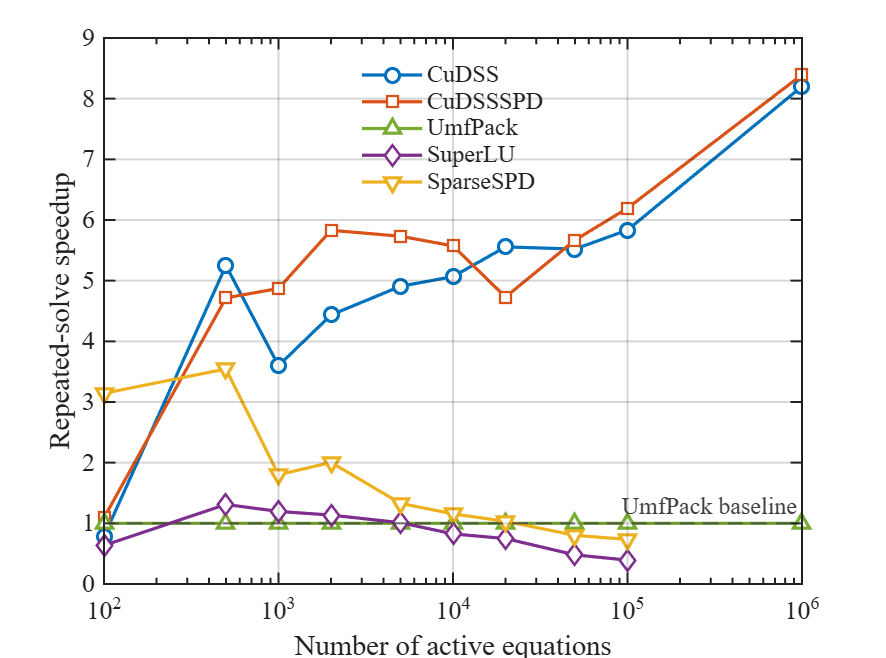

**Solver Selection Recommendations**

- **General nonlinear problems:** Use `CuDSS`, especially above approximately 1,000 equations. It provides a stable 3–4× speedup for larger systems.

- **Guaranteed SPD systems:** Use `CuDSSSPD`. It achieves the best large-model performance, approaching 4–5× speedup.

- **Small SPD systems:** `BandSPD`, `ProfileSPD`, or `SparseSPD` may be faster below approximately 1,000 equations.

- **CPU-only general problems:** Use `UmfPack` as the reliable baseline. `SuperLU` is mainly competitive for smaller systems.

- **Band solvers:** Use only for small, regularly ordered systems with narrow bandwidth. Their performance deteriorates as model size and bandwidth increase.

- **Strong nonlinear earthquake analysis:** Prefer `CuDSS in GPU or Umfpack in CPU` unless the tangent matrix is guaranteed to remain symmetric positive definite throughout the analysis.

**Model:**

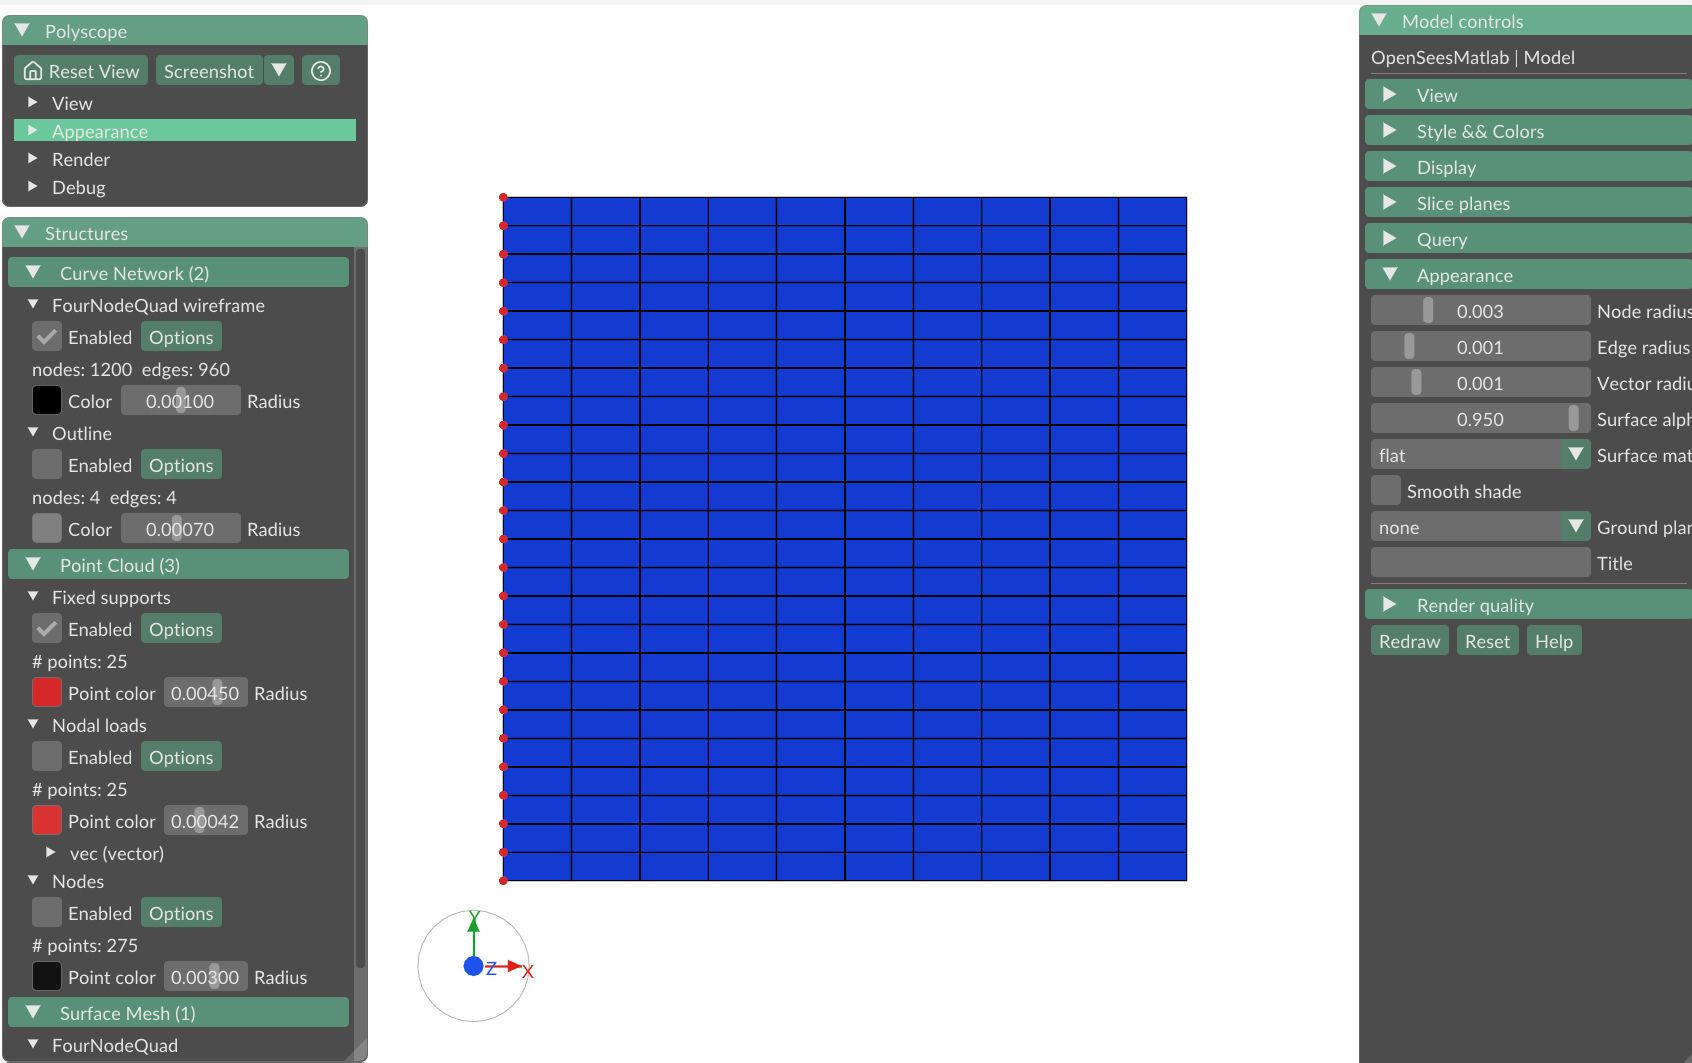

clear;
clc;
close all;

### User requirements and configuration

To select CuDSS, the user machine must provide:

1. A supported NVIDIA GPU and a sufficiently recent NVIDIA display driver.

2. A CUDA runtime supported by the distributed MEX (CUDA 12 or CUDA 13).

3. NVIDIA **cuDSS 0.8** built for the selected CUDA major version.

4. The CUDA and cuDSS runtime DLLs on PATH, or a cuDSS installation supplied

   through **OPENSEES_CUDSS_ROOT** or **RuntimePath** below.

**The user does not need a CUDA-capable GPU to run the CPU solvers.** CUDA is required at build time only when compiling a new GPU-enabled MEX; 

*end users load the CUDA/cuDSS runtime dynamically when ****ops.system('CuDSS')**** is called.*

% for cuda v12.6, for example
cudssPath = "C:\Program Files\NVIDIA cuDSS\v0.8\bin\12";
cudaPath = "C:\Program Files\NVIDIA GPU Computing Toolkit\CUDA\v12.6\bin";

opsMat = OpenSeesMatlab();
ops = opsMat.opensees;

### Benchmark definition

RequestedDOFs = [100 500 1000 2000 5000 10000 20000 50000 100000 1000000];
TargetDOFs = sort(unique(RequestedDOFs,"stable"));
Solvers = ["CuDSS" "CuDSSSPD" "UmfPack" "SuperLU" "SparseSPD"];
NumberOfLoadSteps = 3;

% Iterative refinement is disabled for this comparison. cuDSS 0.8 can report
% CUDSS_STATUS_IR_FAILED for the 100000-DOF case with a very strict 1e-12
% refinement tolerance, while its direct double-precision solution agrees
% with UmfPack to approximately 1e-12 or better.
CuDSSOptions = {"-cudaPath", cudaPath, "-cudssPath", cudssPath, ...
    "-cpuThreshold", 100};

%% Optional cuDSS initialization measurement
% CUDA context and cuDSS runtime initialization occur only on the first GPU
% selection/use in a MATLAB session. Measure that one-time cost separately so
% it does not distort every solver comparison. Set CuDSSAvailable=false after
% a failure and the CPU comparisons will still run normally.

CuDSSAvailable = true;
CuDSSInitializationSeconds = NaN;
try
    initializationTimer = tic;
    runPlaneCase(ops,100,"CuDSS",1,CuDSSOptions);
    CuDSSInitializationSeconds = toc(initializationTimer);
    fprintf("CuDSS initialization plus 100-DOF smoke case: %.4f s\n", ...
        CuDSSInitializationSeconds);
catch exception
    CuDSSAvailable = false;
    warning("CuDSS is unavailable; CPU benchmarks will continue.\n%s", ...
        getReport(exception,"basic","hyperlinks","off"));
end

CuDSS initialization plus 100-DOF smoke case: 3.2151 s


### Run all plane-element cases

% Build time is recorded separately. FirstSolveSeconds measures the first
% analyze(1) call for a newly created system. WarmSolveSeconds is the median
% of the remaining calls and is most representative of a nonlinear history
% analysis that repeatedly solves tangent systems after GPU initialization.

rows = cell(0,1);
for targetDOF = TargetDOFs
    for solver = Solvers
        
        if targetDOF >= 500000 && ~ismember(solver, ["CuDSS", "CuDSSSPD", "UmfPack"])
            fprintf("Skipping target %d DOF with %s...\n", targetDOF, solver);
            continue;
        end


        if ismember(solver, ["CuDSS", "CuDSSSPD"])  && ~CuDSSAvailable
            rows{end+1,1} = failedRow(targetDOF,solver,"cuDSS runtime unavailable"); %#ok<SAGROW>
            continue;
        end

        fprintf("Running target %d DOF with %s...\n",targetDOF,solver);
        try
            rows{end+1,1} = runPlaneCase(ops,targetDOF,solver, ...
                NumberOfLoadSteps,CuDSSOptions); %#ok<SAGROW>
        catch exception
            rows{end+1,1} = failedRow(targetDOF,solver, ...
                string(getReport(exception,"basic","hyperlinks","off"))); %#ok<SAGROW>
        end
    end
end

Running target 100 DOF with CuDSS...
Running target 100 DOF with CuDSSSPD...
Running target 100 DOF with UmfPack...
Running target 100 DOF with SuperLU...
Running target 100 DOF with SparseSPD...
Running target 500 DOF with CuDSS...
Running target 500 DOF with CuDSSSPD...
Running target 500 DOF with UmfPack...
Running target 500 DOF with SuperLU...
Running target 500 DOF with SparseSPD...
Running target 1000 DOF with CuDSS...
Running target 1000 DOF with CuDSSSPD...
Running target 1000 DOF with UmfPack...
Running target 1000 DOF with SuperLU...
Running target 1000 DOF with SparseSPD...
Running target 2000 DOF with CuDSS...
Running target 2000 DOF with CuDSSSPD...
Running target 2000 DOF with UmfPack...
Running target 2000 DOF with SuperLU...
Running target 2000 DOF with SparseSPD...
Running target 5000 DOF with CuDSS...
Running target 5000 DOF with CuDSSSPD...
Running target 5000 DOF with UmfPack...
Running target 5000 DOF with SuperLU...
Running target 5000 DOF with SparseSPD...
Runni

Skipping target 1000000 DOF with SuperLU...
Skipping target 1000000 DOF with SparseSPD...


Results = vertcat(rows{:});

### Calculate accuracy and speedup

% UmfPack is used only as the numerical reference. RelativeTipError compares
% the two-component displacement of the middle node on the loaded edge.

Results.RelativeTipError = NaN(height(Results),1);
Results.FirstSpeedupVsUmfPack = NaN(height(Results),1);
Results.WarmSpeedupVsUmfPack = NaN(height(Results),1);

for targetDOF = unique(Results.TargetDOF)'
    selection = Results.TargetDOF == targetDOF;
    reference = Results(selection & Results.Solver == "UmfPack" & ...
        Results.Status == "ok",:);
    if isempty(reference)
        continue;
    end

    Results.RelativeTipError(selection) = hypot( ...
        Results.TipUx(selection)-reference.TipUx, ...
        Results.TipUy(selection)-reference.TipUy) ./ ...
        max(hypot(reference.TipUx,reference.TipUy),eps);
    Results.FirstSpeedupVsUmfPack(selection) = ...
        reference.FirstSolveSeconds ./ Results.FirstSolveSeconds(selection);
    Results.WarmSpeedupVsUmfPack(selection) = ...
        reference.WarmSolveSeconds ./ Results.WarmSolveSeconds(selection);
end

Results

Results = 48×16 table
    TargetDOF    ActualDOF    Nx    Ny      Solver       Status    BuildSeconds    FirstSolveSeconds    WarmSolveSeconds    TotalSolveSeconds       TipUx          TipUy       Message    RelativeTipError    FirstSpeedupVsUmfPack    WarmSpeedupVsUmfPack
    _________    _________    __    __    ___________    ______    ____________    _________________    ________________    _________________    ___________    ___________    _______    ________________    __

### Plot first and repeated solve times

% Eight distinct solver styles
fontName = "Times New Roman";
fontSize = 13;
lineWidth = 1.6;
markerSize = 7;
axisLineWidth = 1.0;

plotColors = [
    0.0000, 0.4470, 0.7410   % Blue
    0.8500, 0.3250, 0.0980   % Orange
    0.4660, 0.6740, 0.1880   % Green
    0.4940, 0.1840, 0.5560   % Purple
    0.9290, 0.6940, 0.1250   % Yellow
    0.3010, 0.7450, 0.9330   % Cyan
    0.6350, 0.0780, 0.1840   % Dark red
    0.2500, 0.2500, 0.2500   % Dark gray
    ];

plotMarkers = {'o', 's', '^', 'd', 'v', '>', '<', 'p'};

nSolvers = numel(Solvers);

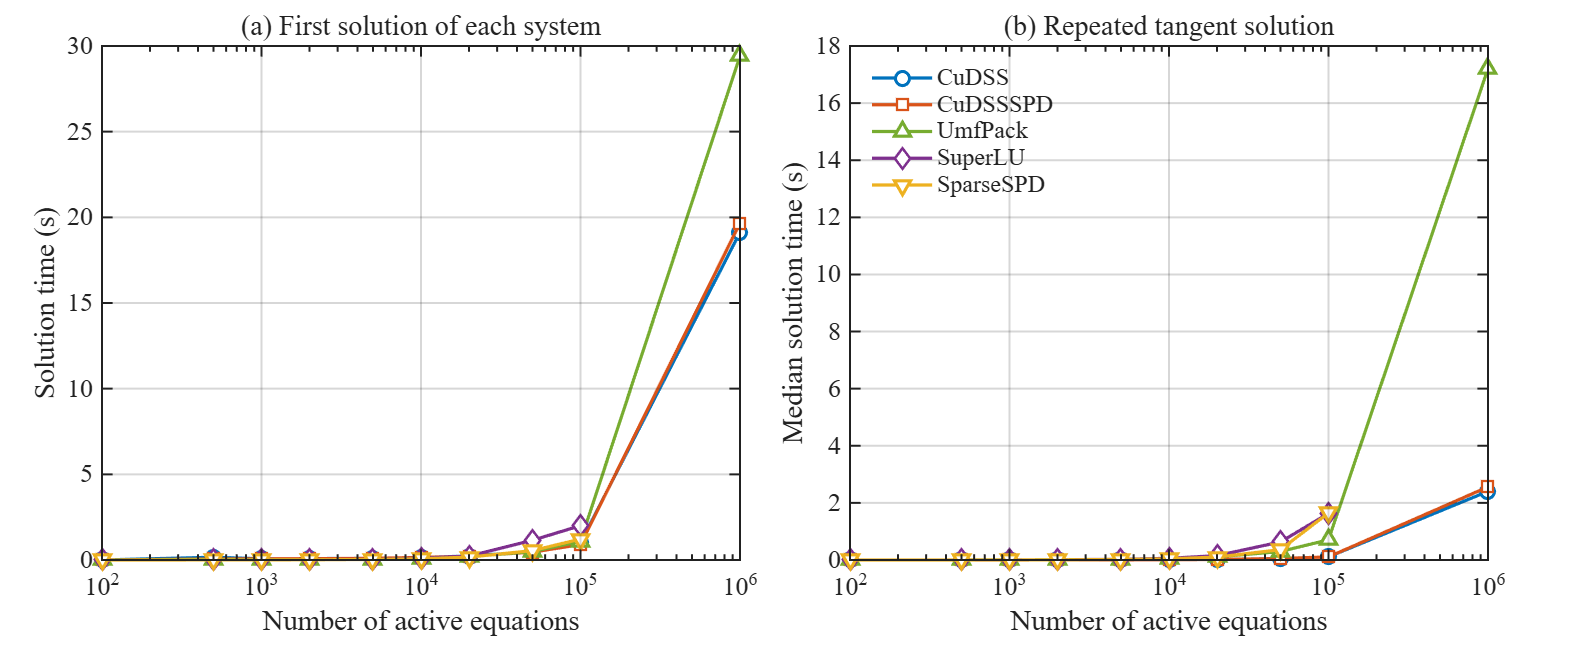

figTime = figure( ...
    "Name", "Plane-element solver time", ...
    "Color", "w", ...
    "Position", [100, 100, 1050, 430]);

tl = tiledlayout(figTime, 1, 2, ...
    "TileSpacing", "compact", ...
    "Padding", "compact");

% -------------------------------------------------------------------------
% First solve
% -------------------------------------------------------------------------

ax1 = nexttile(tl);
hold(ax1, "on");

plotSolverMetric( ...
    ax1, Results, Solvers, "FirstSolveSeconds", ...
    plotColors, plotMarkers, lineWidth, markerSize);

setPublicationAxes(ax1, fontName, fontSize, axisLineWidth);

set(ax1, "XScale", "log");

xlabel(ax1, "Number of active equations");
ylabel(ax1, "Solution time (s)");
title(ax1, "(a) First solution of each system", ...
    "FontWeight", "normal");

% -------------------------------------------------------------------------
% Repeated solve
% -------------------------------------------------------------------------

ax2 = nexttile(tl);
hold(ax2, "on");

plotSolverMetric( ...
    ax2, Results, Solvers, "WarmSolveSeconds", ...
    plotColors, plotMarkers, lineWidth, markerSize);

setPublicationAxes(ax2, fontName, fontSize, axisLineWidth);

set(ax2, "XScale", "log");

xlabel(ax2, "Number of active equations");
ylabel(ax2, "Median solution time (s)");
title(ax2, "(b) Repeated tangent solution", ...
    "FontWeight", "normal");

legend(ax2, ...
    "Location", "northwest", ...
    "Box", "off", ...
    "FontName", fontName, ...
    "FontSize", fontSize - 1);

exportgraphics(figTime, ...
    "CUDSSSolverTime.pdf", ...
    "ContentType", "vector");

### Plot displacement accuracy

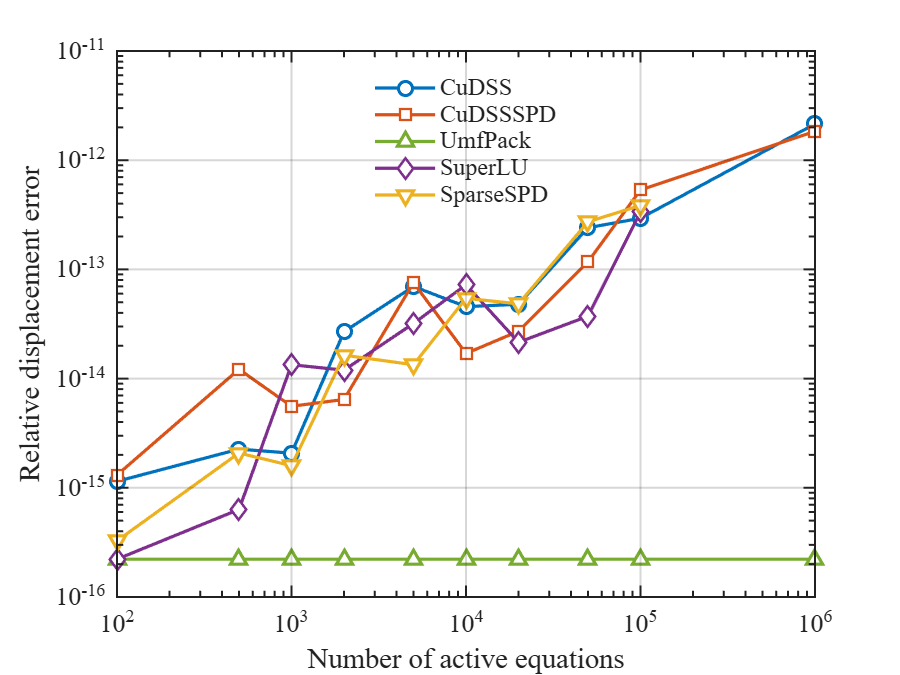

% Zero UmfPack self-error is replaced only for plotting on a logarithmic axis;
% the Results table retains the exact zero.


figAccuracy = figure( ...
    "Name", "Plane-element solver accuracy", ...
    "Color", "w", ...
    "Position", [100, 100, 600, 450]);

ax3 = axes(figAccuracy);
hold(ax3, "on");

for i = 1:nSolvers
    solver = Solvers(i);

    data = Results( ...
        Results.Solver == solver & Results.Status == "ok", :);

    if isempty(data)
        continue;
    end

    data = sortrows(data, "ActualDOF");

    % Replace exact zero only for logarithmic plotting
    plotError = max(abs(data.RelativeTipError), eps);

    loglog(ax3, ...
        data.ActualDOF, ...
        plotError, ...
        "-", ...
        "Color", plotColors(i, :), ...
        "Marker", plotMarkers{mod(i - 1, numel(plotMarkers)) + 1}, ...
        "MarkerSize", markerSize, ...
        "MarkerFaceColor", "w", ...
        "LineWidth", lineWidth, ...
        "DisplayName", solver);
end

setPublicationAxes(ax3, fontName, fontSize, axisLineWidth);

xlabel(ax3, "Number of active equations");
ylabel(ax3, "Relative displacement error");
% title(ax3, "Loaded-edge displacement error relative to UmfPack", ...
%     "FontWeight", "normal");
set(ax3, "XScale", "log");
set(ax3, "YScale", "log");

legend(ax3, ...
    "Location", "best", ...
    "Box", "off", ...
    "FontName", fontName, ...
    "FontSize", fontSize - 1);

exportgraphics(figAccuracy, ...
    "CUDSSSolverAccuracy.pdf", ...
    "ContentType", "vector");

### Plot speedup relative to UmfPack

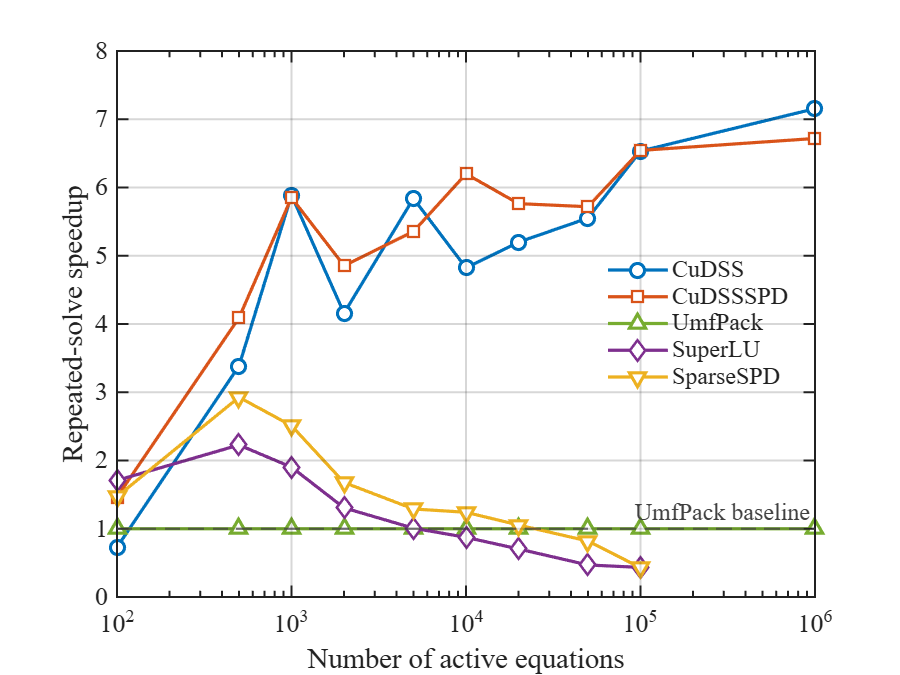

% A value greater than one means that the solver is faster than UmfPack.

figSpeedup = figure( ...
    "Name", "Plane-element solver speedup", ...
    "Color", "w", ...
    "Position", [100, 100, 600, 450]);

ax4 = axes(figSpeedup);
hold(ax4, "on");

for i = 1:nSolvers
    solver = Solvers(i);

    data = Results( ...
        Results.Solver == solver & Results.Status == "ok", :);

    if isempty(data)
        continue;
    end

    data = sortrows(data, "ActualDOF");

    semilogx(ax4, ...
        data.ActualDOF, ...
        data.WarmSpeedupVsUmfPack, ...
        "-", ...
        "Color", plotColors(i, :), ...
        "Marker", plotMarkers{mod(i - 1, numel(plotMarkers)) + 1}, ...
        "MarkerSize", markerSize, ...
        "MarkerFaceColor", "w", ...
        "LineWidth", lineWidth, ...
        "DisplayName", solver);
end

set(ax4, "XScale", "log");
% set(ax4, "YScale", "log");

yline(ax4, ...
    1.0, ...
    "--", ...
    "UmfPack baseline", ...
    "Color", [0.25, 0.25, 0.25], ...
    "LineWidth", 1.1, ...
    "LabelHorizontalAlignment", "right", ...
    "LabelVerticalAlignment", "top", ...
    "FontName", fontName, ...
    "FontSize", fontSize - 1, ...
    "HandleVisibility", "off");

setPublicationAxes(ax4, fontName, fontSize, axisLineWidth);

xlabel(ax4, "Number of active equations");
ylabel(ax4, "Repeated-solve speedup");
% title(ax4, "Solver speedup relative to UmfPack", ...
%     "FontWeight", "normal");

legend(ax4, ...
    "Location", "best", ...
    "Box", "off", ...
    "FontName", fontName, ...
    "FontSize", fontSize - 1);


% exportgraphics(figSpeedup, ...
%     "CUDSSSolverSpeedup.pdf", ...
%     "ContentType", "vector");

### Local benchmark functions

function row = runPlaneCase(ops,targetDOF,solver,numberOfSteps,cudssOptions)
    [nx,ny,actualDOF] = balancedMesh(targetDOF);
    % cleanup = onCleanup(@() ops.wipe());
    
    buildTimer = tic;
    ops.wipe();
    ops.model("basic","-ndm",2,"-ndf",2);
    ops.nDMaterial("ElasticIsotropic",1,2.0e11,0.30,7850.0);
    ops.block2D(nx,ny,1,1,"quad",0.10,"PlaneStress",1, ...
        1,0,0, 2,10,0, 3,10,10, 4,0,10);
    ops.fixX(0.0,1,1);
    ops.timeSeries("Linear",1);
    ops.pattern("Plain",1,1);
    
    rightEdgeTags = (0:ny)*(nx+1)+nx+1;
    verticalLoad = -1.0e6/numel(rightEdgeTags);
    for nodeTag = rightEdgeTags
        ops.load(nodeTag,0.0,verticalLoad);
    end
    buildSeconds = toc(buildTimer);
    
    ops.constraints("Plain");
    ops.numberer("RCM");
    selectSystem(ops,solver,cudssOptions);
    ops.integrator("LoadControl",1/numberOfSteps);
    ops.algorithm("Linear");
    ops.analysis("Static");
    
    solveSeconds = zeros(1,numberOfSteps);
    for step = 1:numberOfSteps
        solveTimer = tic;
        returnCode = ops.analyze(1);
        solveSeconds(step) = toc(solveTimer);
        if returnCode ~= 0
            error("CuDSSExample:AnalyzeFailed", ...
                "ops.analyze returned %d at load step %d.",returnCode,step);
        end
    end
    
    middleRightTag = floor(ny/2)*(nx+1)+nx+1;
    tipDisplacement = ops.nodeDisp(middleRightTag);
    if numberOfSteps > 1
        warmSeconds = median(solveSeconds(2:end));
    else
        warmSeconds = NaN;
    end
    
    row = table(targetDOF,actualDOF,nx,ny,solver,"ok",buildSeconds, ...
        solveSeconds(1),warmSeconds,sum(solveSeconds), ...
        tipDisplacement(1),tipDisplacement(2),"", ...
        'VariableNames',{'TargetDOF','ActualDOF','Nx','Ny','Solver','Status', ...
        'BuildSeconds','FirstSolveSeconds','WarmSolveSeconds','TotalSolveSeconds', ...
        'TipUx','TipUy','Message'});
end

function selectSystem(ops,solver,cudssOptions)
    switch solver
        case "CuDSS"
            ops.system("CuDSS",cudssOptions{:});
        case "CuDSSSPD"
            ops.system("CuDSSSPD",cudssOptions{:});
        case "UmfPack"
            ops.system("UmfPack");
        case "SuperLU"
            ops.system("SuperLU");
        case "SparseSPD"
            ops.system("SparseSPD");
        case "BandGeneral"
            ops.system("BandGeneral");
        case "ProfileSPD"
            ops.system("ProfileSPD")
        case "BandSPD"
            ops.system("BandSPD")
        otherwise
            error("CuDSSExample:UnknownSolver","Unknown solver: %s",solver);
    end
end

function row = failedRow(targetDOF,solver,message)
    row = table(targetDOF,NaN,NaN,NaN,solver,"failed",NaN,NaN,NaN,NaN, ...
        NaN,NaN,string(message), ...
        'VariableNames',{'TargetDOF','ActualDOF','Nx','Ny','Solver','Status', ...
        'BuildSeconds','FirstSolveSeconds','WarmSolveSeconds','TotalSolveSeconds', ...
        'TipUx','TipUy','Message'});
end

function plotMetric(results,metric,solvers)
    hold on;
    for solver = solvers
        data = results(results.Solver == solver & results.Status == "ok",:);
        loglog(data.ActualDOF,data.(metric),"-o","LineWidth",1.4, ...
            "DisplayName",solver);
    end
    grid on;
    xlabel("Active equations");
end

function [nx,ny,actualDOF] = balancedMesh(targetDOF)
    center = max(1,round(sqrt(targetDOF/2)));
    best = [Inf Inf 1 1];
    for nxCandidate = max(1,center-20):center+20
        estimatedNy = max(1,round(targetDOF/(2*nxCandidate)-1));
        for nyCandidate = max(1,estimatedNy-1):estimatedNy+1
            candidateDOF = 2*nxCandidate*(nyCandidate+1);
            score = [abs(candidateDOF-targetDOF), ...
                abs(nxCandidate-nyCandidate),nxCandidate,nyCandidate];
            changedIndex = find(score ~= best,1);
            if ~isempty(changedIndex) && score(changedIndex) < best(changedIndex)
                best = score;
            end
        end
    end
    nx = best(3);
    ny = best(4);
    actualDOF = 2*nx*(ny+1);
end

function plotSolverMetric( ...
    ax, Results, Solvers, metricName, ...
    plotColors, plotMarkers, lineWidth, markerSize)

for i = 1:numel(Solvers)
    solver = Solvers(i);

    data = Results( ...
        Results.Solver == solver & Results.Status == "ok", :);

    if isempty(data)
        continue;
    end

    data = sortrows(data, "ActualDOF");

    x = data.ActualDOF;
    y = data.(metricName);

    valid = isfinite(x) & isfinite(y) & x > 0 & y >= 0;

    plot(ax, ...
        x(valid), ...
        y(valid), ...
        "-", ...
        "Color", plotColors(i, :), ...
        "Marker", plotMarkers{mod(i - 1, numel(plotMarkers)) + 1}, ...
        "MarkerSize", markerSize, ...
        "MarkerFaceColor", "w", ...
        "LineWidth", lineWidth, ...
        "DisplayName", solver);
end
end


function setPublicationAxes(ax, fontName, fontSize, axisLineWidth)

box(ax, "on");
grid(ax, "on");

ax.XMinorGrid = "off";
ax.YMinorGrid = "off";
ax.GridAlpha = 0.18;
ax.GridLineStyle = "-";

set(ax, ...
    "FontName", fontName, ...
    "FontSize", fontSize, ...
    "LineWidth", axisLineWidth, ...
    "TickDir", "in", ...
    "TickLength", [0.015, 0.015], ...
    "Layer", "top");

ax.XLabel.FontName = fontName;
ax.YLabel.FontName = fontName;
ax.Title.FontName = fontName;
ax.XLabel.FontSize = fontSize + 1;
ax.YLabel.FontSize = fontSize + 1;
ax.Title.FontSize = fontSize + 1;
end
